clc
clear all

## Reading run file

Here you can import .csv file from the datasets. you should pick as type COLUMN VECTORS. For Cerberus you should add to the data the altitude and the heartrate because Diego likes it. 

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["timestamp", "altitude", "heart_rate", "cadence", "distance", "speed", "power"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "timestamp", "InputFormat", "yyyy-MM-dd'T'HH:mm:ss");

% Import the data
Diego_15_09_2023_PM_2 = readtable("/home/lorenzo/Documents/Data-Analysis-Policumbent/BM_23/Cerberus/Diego_15_09_2023_PM_2.csv", opts);

% Convert to output type
timestamp = Diego_15_09_2023_PM_2.timestamp;
altitude = Diego_15_09_2023_PM_2.altitude;
heart_rate = Diego_15_09_2023_PM_2.heart_rate;
cadence = Diego_15_09_2023_PM_2.cadence;
distance = Diego_15_09_2023_PM_2.distance;
speed = Diego_15_09_2023_PM_2.speed;
power = Diego_15_09_2023_PM_2.power;

% Clear temporary variables
clear Diego_15_09_2023_PM_2

% Clear temporary variables
clear opts
time = 1:size(power);   % We have a sample every second, easy as it is.

## Data visualization

Just data plotting, remember to add altitude and heartrate for Diego because he likes it.

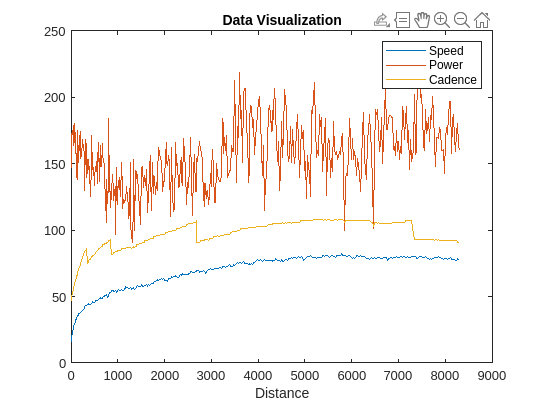

plot(distance,speed,distance,power,distance,cadence);
legend("Speed","Power","Cadence");
title("Data Visualization");
xlabel("Distance");

avg_power = mean(power)

avg_power = 156.0605

avg_power_last_km = mean(power(288:end))

avg_power_last_km = 167.5975

## System modeling

sys = [speed,power];
nx = 1;
model = n4sid(sys,nx);

## Simulation

As seen by the real data, the best speed is reached by using an incremental linear power input. Down here you can modify the values of each line of power.

k = size(power,1);
a = 0.829;
b = 1.15;
ScatterFactor = a+(b-a)*rand(k,1);

Here you have to choose the slope of each segment of the power line. The standard coefficients usually fit well but the choice is up to you.

m1 = 0.7;
m2 = 1.1;
m3 = 0.95;

Here you can choose the average power input for each segment. The lenght of the ScatterFactor in each segment is measured is seconds and it corresponds to the time each power input has to be maintained by the rider. You can choose the lenght of each segment by modifying t1, t2, t3, t4. 

**The sum of t1, t2, t3, t4 must be k, whitch is the lengh of the training dataset, the s variables do just so.**

t1 = 100; s2 = k-t1;
t2 = 110; s3 = k-t1-t2;
t3 = 100; s4 = k-t1-t2-t3;
t4 = 136; 
x1 = ScatterFactor(1:t1)*130;
x2 = ScatterFactor(1:t2)*140;
x3 = ScatterFactor(1:t3)*200;
x4 = ScatterFactor(1:t4)*170;
y1 = m1*x1;
y2 = x2;
y3 = m2*x3;
y4 = x4;

Just vector concatenation, simulation and plotting.

Sim_power_lin = [y1',y2',y3',y4']';
simSpeed = sim(model,Sim_power_lin);
max_speed = max(simSpeed)

max_speed = 93.3975

trap_speed = simSpeed(end)

trap_speed = 86.1418

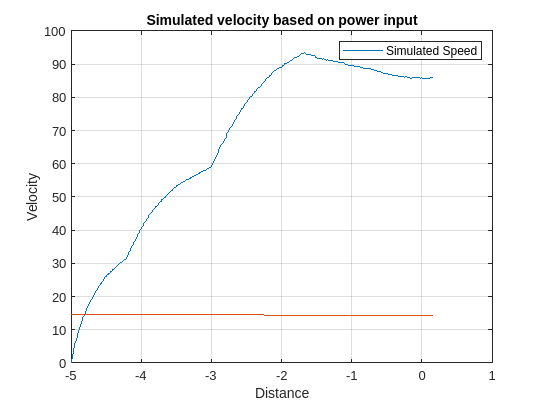

dist_mile = distance/1609;

plot(dist_mile-5, simSpeed,dist_mile-5,altitude/100);
title("Simulated velocity based on power input");
legend("Simulated Speed");
xlabel("Distance");
ylabel("Velocity");
grid on;